Group Project 2

CAPM and a multivariate model of stock returns

Variables:            

Sector portfolio excess returns (return minus the risk free rate)

BMATRUSER  Building materials

INDUSUSER   Industrials

CNSMGUSER  Consumer goods

FINANUSER  Financials

TECNOUSER  Technology

MktRF:   Market return - risk free rate

SMB    Fama-French Small minus Big  

HML    Fama- French  High minus Low 

RF risk free rate

% import data


%rename variables 
BMATRUSER = returns{ : ,2};
INDUSUSER = returns{ : ,3};
CNSMGUSER = returns{ : ,4};
FINANUSER = returns{ : ,5};
TECNOUSER = returns{ : ,6};
MktRF = returns{ : ,7};
SMB = returns{ : ,8};
HML = returns{ : ,9};



CAPM estimation

***************************************************************************************************************

Q1.       (10 points) Estimate CAPM regressions for each of the 5 portfolios and report the results. 

             Is the CAPM rejected?

%INSERT CODE
x1 = table(MktRF,BMATRUSER);
lm1 = fitlm(x1)

lm1 = Linear regression model:
    BMATRUSER ~ 1 + MktRF

Estimated Coefficients:
                   Estimate       SE       tStat      pValue  
                   ________    ________    ______    _________

    (Intercept)     0.73685     0.27321     2.697    0.0072198
    MktRF          0.081883    0.061673    1.3277      0.18485


Number of observations: 532, Error degrees of freedom: 530
Root Mean Squared Error: 6.23
R-squared: 0.00331,  Adjusted R-Squared: 0.00143
F-statistic vs. constant model: 1.76, p-value = 0.185

x2 = table(MktRF,INDUSUSER);
lm1 = fitlm(x2), 

lm1 = Linear regression model:
    INDUSUSER ~ 1 + MktRF

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)    0.91565      0.23429    3.9081    0.00010506
    MktRF          0.10704     0.052887     2.024      0.043473


Number of observations: 532, Error degrees of freedom: 530
Root Mean Squared Error: 5.34
R-squared: 0.00767,  Adjusted R-Squared: 0.0058
F-statistic vs. constant model: 4.1, p-value = 0.0435

x3 = table(MktRF,CNSMGUSER);
lm1 = fitlm(x3)

lm1 = Linear regression model:
    CNSMGUSER ~ 1 + MktRF

Estimated Coefficients:
                   Estimate       SE       tStat      pValue  
                   ________    ________    ______    _________

    (Intercept)     0.67519     0.22407    3.0133    0.0027079
    MktRF          0.028628    0.050579     0.566      0.57163


Number of observations: 532, Error degrees of freedom: 530
Root Mean Squared Error: 5.11
R-squared: 0.000604,  Adjusted R-Squared: -0.00128
F-statistic vs. constant model: 0.32, p-value = 0.572

x4 = table(MktRF,FINANUSER);
lm1 = fitlm(x4)

lm1 = Linear regression model:
    FINANUSER ~ 1 + MktRF

Estimated Coefficients:
                   Estimate       SE       tStat      pValue  
                   ________    ________    ______    _________

    (Intercept)    0.80996      0.24665    3.2838    0.0010918
    MktRF          0.14648     0.055677    2.6309    0.0087637


Number of observations: 532, Error degrees of freedom: 530
Root Mean Squared Error: 5.63
R-squared: 0.0129,  Adjusted R-Squared: 0.011
F-statistic vs. constant model: 6.92, p-value = 0.00876

x5 = table(MktRF,TECNOUSER);
lm1 = fitlm(x5)

lm1 = Linear regression model:
    TECNOUSER ~ 1 + MktRF

Estimated Coefficients:
                   Estimate       SE       tStat      pValue 
                   ________    ________    ______    ________

    (Intercept)     1.0117      0.29754    3.4002    0.000724
    MktRF          0.11309     0.067165    1.6838    0.092812


Number of observations: 532, Error degrees of freedom: 530
Root Mean Squared Error: 6.79
R-squared: 0.00532,  Adjusted R-Squared: 0.00344
F-statistic vs. constant model: 2.84, p-value = 0.0928

Answer: 

****************************************************************************************************************

Q2. (6 points) Do the residuals of the CAPM regressions appear to be distributed normally, exhibit heteroskedasticity and autocorrelation? 

 Answer this question for INDUSUSER, FINANUSER, and TECNOUSER

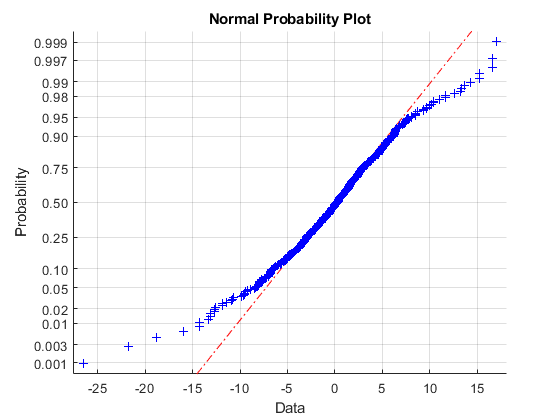

% INSERT CODE
x1 = table(MktRF,INDUSUSER);
lm1 = fitlm(x1);
resid = Md1.Residuals.Raw(~isnan(Md1.Residuals.Raw));
normplot(resid)

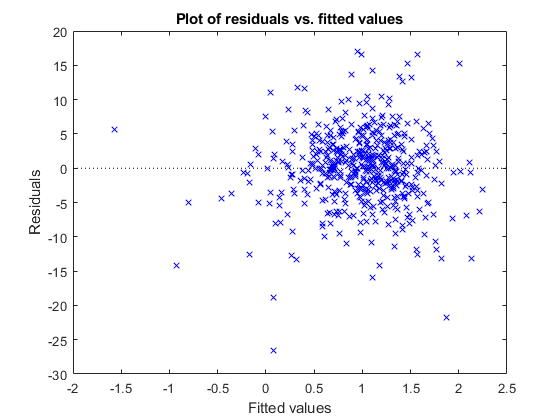

plotResiduals(lm1,'fitted')

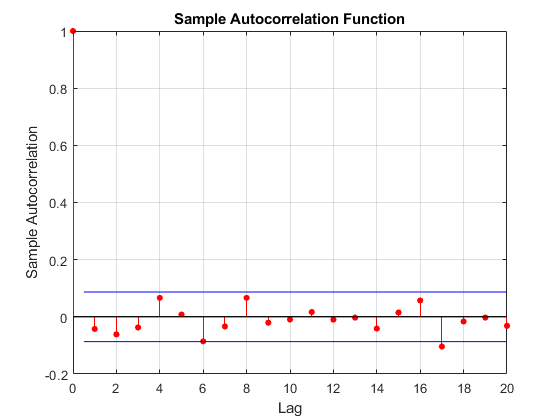

autocorr(resid)


x1 = table(MktRF,FINANUSER);
lm1 = fitlm(x1);
resid = Md1.Residuals.Raw(~isnan(Md1.Residuals.Raw));
normplot(resid)

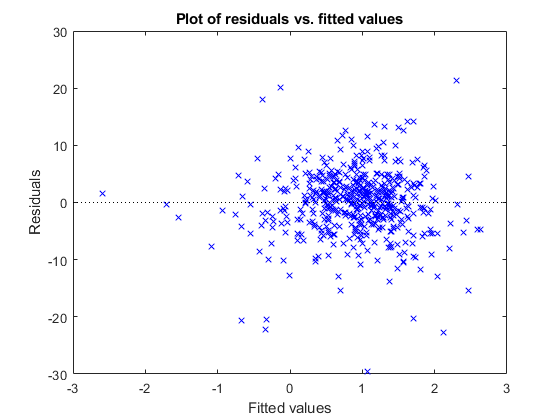

plotResiduals(lm1,'fitted')

autocorr(resid)


x1 = table(MktRF,TECNOUSER);
lm1 = fitlm(x1);
resid = Md1.Residuals.Raw(~isnan(Md1.Residuals.Raw));
normplot(resid)

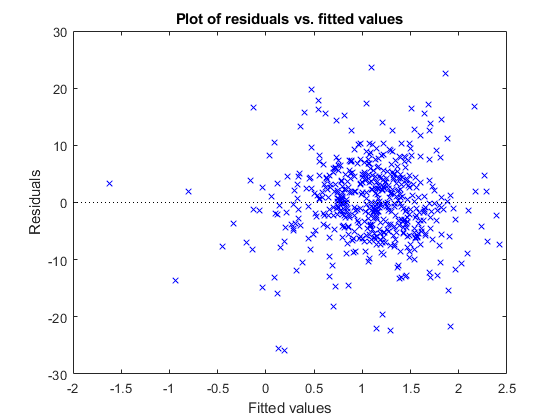

plotResiduals(lm1,'fitted')

autocorr(resid)

***********************************************************************************************************************

Q3. (6 points) Compute the HAC standard errors for the CAPM regressions of INDUSUSER, FINANUSER, and TECNOUSER.

 Are they different from the OLS standard errors?

% INSERT CODE
x1 = table(MktRF,INDUSUSER);
lm1 = fitlm(x1)

lm1 = Linear regression model:
    INDUSUSER ~ 1 + MktRF

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)    0.91565      0.23429    3.9081    0.00010506
    MktRF          0.10704     0.052887     2.024      0.043473


Number of observations: 532, Error degrees of freedom: 530
Root Mean Squared Error: 5.34
R-squared: 0.00767,  Adjusted R-Squared: 0.0058
F-statistic vs. constant model: 4.1, p-value = 0.0435

[EstCov,es,coeff] = hac(lm1)


Estimator type: HAC
Estimation method: BT
Bandwidth: 4.4884
Whitening order: 0
Effective sample size: 532
Small sample correction: on

Coefficient Covariances:

       |  Const    MktRF  
--------------------------
 Const |  0.0510  -0.0050 
 MktRF | -0.0050   0.0036 


EstCov =     0.0510   -0.0050
   -0.0050    0.0036


es =     0.2258
    0.0601


coeff =     0.9157
    0.1070



x1 = table(MktRF,FINANUSER);
lm1 = fitlm(x1)

lm1 = Linear regression model:
    FINANUSER ~ 1 + MktRF

Estimated Coefficients:
                   Estimate       SE       tStat      pValue  
                   ________    ________    ______    _________

    (Intercept)    0.80996      0.24665    3.2838    0.0010918
    MktRF          0.14648     0.055677    2.6309    0.0087637


Number of observations: 532, Error degrees of freedom: 530
Root Mean Squared Error: 5.63
R-squared: 0.0129,  Adjusted R-Squared: 0.011
F-statistic vs. constant model: 6.92, p-value = 0.00876

[EstCov,es,coeff] = hac(lm1)


Estimator type: HAC
Estimation method: BT
Bandwidth: 6.1959
Whitening order: 0
Effective sample size: 532
Small sample correction: on

Coefficient Covariances:

       |  Const    MktRF  
--------------------------
 Const |  0.0555  -0.0034 
 MktRF | -0.0034   0.0029 


EstCov =     0.0555   -0.0034
   -0.0034    0.0029


es =     0.2356
    0.0542


coeff =     0.8100
    0.1465



x1 = table(MktRF,TECNOUSER);
lm1 = fitlm(x1)

lm1 = Linear regression model:
    TECNOUSER ~ 1 + MktRF

Estimated Coefficients:
                   Estimate       SE       tStat      pValue 
                   ________    ________    ______    ________

    (Intercept)     1.0117      0.29754    3.4002    0.000724
    MktRF          0.11309     0.067165    1.6838    0.092812


Number of observations: 532, Error degrees of freedom: 530
Root Mean Squared Error: 6.79
R-squared: 0.00532,  Adjusted R-Squared: 0.00344
F-statistic vs. constant model: 2.84, p-value = 0.0928

[EstCov,es,coeff] = hac(lm1)


Estimator type: HAC
Estimation method: BT
Bandwidth: 4.1440
Whitening order: 0
Effective sample size: 532
Small sample correction: on

Coefficient Covariances:

       |  Const    MktRF  
--------------------------
 Const |  0.0836  -0.0055 
 MktRF | -0.0055   0.0049 


EstCov =     0.0836   -0.0055
   -0.0055    0.0049


es =     0.2892
    0.0699


coeff =     1.0117
    0.1131


Answer: 

***********************************************************************************************************************

***********************************************************************************************************************

Q4. (2 points) Compute the coerrelation matrix of  Mkt-RF, SMB, HML. Are these highly correlated?    


% correlationn matrix
corrcoef(returns{ :,6:8})

ans =     1.0000    0.0729    0.1283
    0.0729    1.0000    0.2407
    0.1283    0.2407    1.0000


Answer: 

***********************************************************************************************************************

Q5.  (20 points) Estimate a multivariate regression adding SMB and HML to the CAPM regressions for each of the 5 portfolios.. 

a. Is the constant statistically significant? 

b. Are SMB and HML significant?

c. Are there significant diffrences between the coefficient of MktRF in the original CAPM regression and in the multivariate regression? 

d. Any omitted variable bias?

% insert code
x1 = table(MktRF,SMB,HML, BMATRUSER);
lm1 = fitlm(x1)

lm1 = Linear regression model:
    BMATRUSER ~ 1 + MktRF + SMB + HML

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     0.60822      0.2718    2.2377      0.025654
    MktRF          0.065687    0.064067    1.0253        0.3057
    SMB             0.35893    0.093689    3.8311    0.00014292
    HML             0.25323    0.097814    2.5889     0.0098944


Number of observations: 532, Error degrees of freedom: 528
Root Mean Squared Error: 6.14
R-squared: 0.0371,  Adjusted R-Squared: 0.0317
F-statistic vs. constant model: 6.79, p-value = 0.00017

x2 = table(MktRF,SMB,HML,INDUSUSER);
lm1 = fitlm(x2)

lm1 = Linear regression model:
    INDUSUSER ~ 1 + MktRF + SMB + HML

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     0.80926     0.23352    3.4654    0.00057247
    MktRF          0.095806    0.055045    1.7405      0.082353
    SMB             0.28649    0.080495    3.5591    0.00040564
    HML             0.21224    0.084039    2.5254      0.011847


Number of observations: 532, Error degrees of freedom: 528
Root Mean Squared Error: 5.27
R-squared: 0.0377,  Adjusted R-Squared: 0.0322
F-statistic vs. constant model: 6.89, p-value = 0.000147

x3 = table(MktRF,SMB,HML,CNSMGUSER);
lm1 = fitlm(x3)

lm1 = Linear regression model:
    CNSMGUSER ~ 1 + MktRF + SMB + HML

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)    0.54264      0.22125     2.4527      0.014503
    MktRF          0.01853     0.052151    0.35531        0.7225
    SMB            0.33823     0.076263     4.4351    1.1206e-05
    HML             0.2695     0.079621     3.3848    0.00076533


Number of observations: 532, Error degrees of freedom: 528
Root Mean Squared Error: 4.99
R-squared: 0.0489,  Adjusted R-Squared: 0.0435
F-statistic vs. constant model: 9.04, p-value = 7.55e-06

x4 = table(MktRF,SMB,HML,FINANUSER);
lm1 = fitlm(x4)

lm1 = Linear regression model:
    FINANUSER ~ 1 + MktRF + SMB + HML

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)    0.69691        0.245    2.8446     0.0046198
    MktRF          0.12495      0.05775    2.1637      0.030933
    SMB            0.35042      0.08445    4.1494    3.8847e-05
    HML            0.21306     0.088169    2.4165       0.01601


Number of observations: 532, Error degrees of freedom: 528
Root Mean Squared Error: 5.53
R-squared: 0.0493,  Adjusted R-Squared: 0.0439
F-statistic vs. constant model: 9.13, p-value = 6.7e-06

x5 = table(MktRF,SMB,HML,TECNOUSER);
lm1 = fitlm(x5)

lm1 = Linear regression model:
    TECNOUSER ~ 1 + MktRF + SMB + HML

Estimated Coefficients:
                   Estimate       SE       tStat      pValue  
                   ________    ________    ______    _________

    (Intercept)    0.87429      0.29713    2.9424    0.0033999
    MktRF          0.10988     0.070039    1.5689      0.11728
    SMB            0.31586      0.10242    3.0839    0.0021498
    HML            0.28887      0.10693    2.7014    0.0071258


Number of observations: 532, Error degrees of freedom: 528
Root Mean Squared Error: 6.71
R-squared: 0.0317,  Adjusted R-Squared: 0.0262
F-statistic vs. constant model: 5.76, p-value = 0.000696

Answer: 

***********************************************************************************************************